# Mean Variance Plot

## Data Provided for Solution

The hiistorical annualized returns, annualized volatilities and the correlation matrix of Alphabet (GOOGL), Apple (AAPL), Facebook (FB), and Microsoft (MSFT) in this order.

m = [0.2626; 0.2769; 0.2538; 0.3001];

sigma = [0.25; 0.2796; 0.3113; 0.218];

cor = [1, 0.713, 0.753, 0.821;
       0.713, 1, 0.712, 0.811;
       0.753, 0.712, 1, 0.716;
       0.821, 0.811, 0.716, 1];

Converting the correlation matrix to covariance matrix

cov = corr2cov(sigma, cor)

cov =     0.0625    0.0498    0.0586    0.0447
    0.0498    0.0782    0.0620    0.0494
    0.0586    0.0620    0.0969    0.0486
    0.0447    0.0494    0.0486    0.0475


Also, the portfolio returns $r_T$ values are given as:

r_T_values = [0.2, 0.4];

Obtaining the minimum volatilities $\sigma$ for the $r_T$ values.

sigma_min = zeros(1, [length(r_T_values)])

sigma_min =      0     0



i = 1;
for r_T = r_T_values
    
    var_min = Q2c(r_T, m, cov);
    
    sigma_min(i) = sqrt(var_min);
    i = i + 1;
end

The value of $\sigma_{min}$ after optimization

sigma_min

sigma_min =     0.3939    0.4083


## Mean-Variance Plot

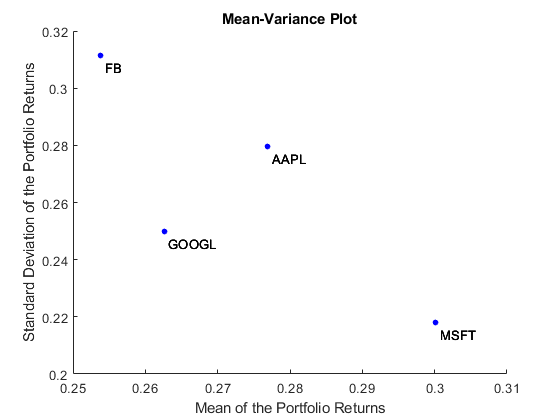

figure(1)
scatter(m, sigma, 20, 'blue', 'filled')
hold on
labels = {'GOOGL', 'AAPL', 'FB', 'MSFT'};
labelpoints(m, sigma,labels,'SE',0.2,1)
hold on
plot(r_T_values, sigma_min, '-r')
title('Mean-Variance Plot')
xlabel('Mean of the Portfolio Returns')
ylabel('Standard Deviation of the Portfolio Returns')